# ARX Models

Pieter Leon van den Berg

22684166

19 July 2022

Final Year Project (C) 478

Supervisor: Dr Cripwell

### ARX Models

Fit ARX models to the copper solvent extraction model to use for controller tuning

## Setup

### MATLAB Simulink

clear;
clc;

### Plotting

opengl software

### Plot colours

orange = '#FF9A5B';
blue   = '#06ACE9';

## ARX Properties

% Loop for gamma from 0 to 30
gamma_bound = 30; 

## Step in v_LO

### Read the Step Data

STEP_V_LO_TABLE = readtable('controller_tuning/data/step_v_LO_control.csv');

### Extract the Data

% Extract the model time
STEP_V_LO_time          = STEP_V_LO_TABLE.Time;

% Extract the valve position of v_LO_control
STEP_V_LO_v_LO_control  = STEP_V_LO_TABLE.v_LO_control;

% Extract the controlled variables
STEP_V_LO_c_LO_measured = STEP_V_LO_TABLE.c_LO_measured;
STEP_V_LO_c_RE_measured = STEP_V_LO_TABLE.c_RE_measured;

### Deviation variable form

% Valve position
STEP_V_LO_v_LO_control_prime  = STEP_V_LO_v_LO_control - STEP_V_LO_v_LO_control(1);

% Controlled variables
STEP_V_LO_c_LO_measured_prime = STEP_V_LO_c_LO_measured - STEP_V_LO_c_LO_measured(1);
STEP_V_LO_c_RE_measured_prime = STEP_V_LO_c_RE_measured - STEP_V_LO_c_RE_measured(1);

### Time step

STEP_V_LO_delta_t = STEP_V_LO_time(2) - STEP_V_LO_time(1);  % [s]

### Time in Hours

STEP_V_LO_time_hours = STEP_V_LO_time / (60*60);            % [h]

## Change in c_LO

### ARX model

for STEP_V_LO_c_LO_gamma = 0:gamma_bound  
    % Set up the system
    STEP_V_LO_c_LO_U = [STEP_V_LO_c_LO_measured_prime((1+STEP_V_LO_c_LO_gamma):(end-1)), STEP_V_LO_v_LO_control_prime(1:(end-1-STEP_V_LO_c_LO_gamma))];
    STEP_V_LO_c_LO_z = STEP_V_LO_c_LO_measured_prime((2+STEP_V_LO_c_LO_gamma):end);
    
    % Perform the linear regression
    STEP_V_LO_c_LO_w = STEP_V_LO_c_LO_U\STEP_V_LO_c_LO_z;
    STEP_V_LO_c_LO_a = STEP_V_LO_c_LO_w(1);
    STEP_V_LO_c_LO_b = STEP_V_LO_c_LO_w(2);
    
    % Calcalate the predicted values
    STEP_V_LO_c_LO_predicted = STEP_V_LO_c_LO_U*STEP_V_LO_c_LO_w;
    
    % Calculate the MSE
    STEP_V_LO_c_LO_MSE(STEP_V_LO_c_LO_gamma+1) = mean((STEP_V_LO_c_LO_predicted - STEP_V_LO_c_LO_z).^2);
    
    % Calculate the transfer function constants
    STEP_V_LO_c_LO_tau(STEP_V_LO_c_LO_gamma+1)   = (-STEP_V_LO_delta_t)/log(STEP_V_LO_c_LO_a);
    STEP_V_LO_c_LO_Kp(STEP_V_LO_c_LO_gamma+1)    = (STEP_V_LO_c_LO_b)/(1-STEP_V_LO_c_LO_a);
    STEP_V_LO_c_LO_theta(STEP_V_LO_c_LO_gamma+1) = (STEP_V_LO_c_LO_gamma)*(STEP_V_LO_delta_t);
    
end

### Find the optimal gamma value

% Find the optimal gamma value
STEP_V_LO_c_LO_gamma_optimal_index = find(STEP_V_LO_c_LO_MSE == min(STEP_V_LO_c_LO_MSE));

% Find the optimal transfer function values
STEP_V_LO_c_LO_gamma_optimal = STEP_V_LO_c_LO_gamma_optimal_index - 1;
STEP_V_LO_c_LO_tau_optimal   = STEP_V_LO_c_LO_tau(STEP_V_LO_c_LO_gamma_optimal_index);
STEP_V_LO_c_LO_Kp_optimal    = STEP_V_LO_c_LO_Kp(STEP_V_LO_c_LO_gamma_optimal_index);
STEP_V_LO_c_LO_theta_optimal = STEP_V_LO_c_LO_theta(STEP_V_LO_c_LO_gamma_optimal_index);

### Simulate the transfer function using Simulink

% Setup the Simulink transfer functions
simulink_Kp    = STEP_V_LO_c_LO_Kp_optimal;
simulink_tau   = STEP_V_LO_c_LO_tau_optimal;
simulink_theta = STEP_V_LO_c_LO_theta_optimal;

% Feed the data to Simulink
simulink_feed    = [STEP_V_LO_time STEP_V_LO_v_LO_control_prime];
simulink_results = sim('controller_tuning/arx_models/arx_models.slx');

% Extract the Simulink transfer function fit
STEP_V_LO_c_LO_transfer_function_results    = simulink_results.transfer_function_results.Data;
STEP_V_LO_c_LO_transfer_function_time       = simulink_results.tout;
STEP_V_LO_c_LO_transfer_function_time_hours = simulink_results.tout / (60*60);

### Plot the ARX model of c_LO

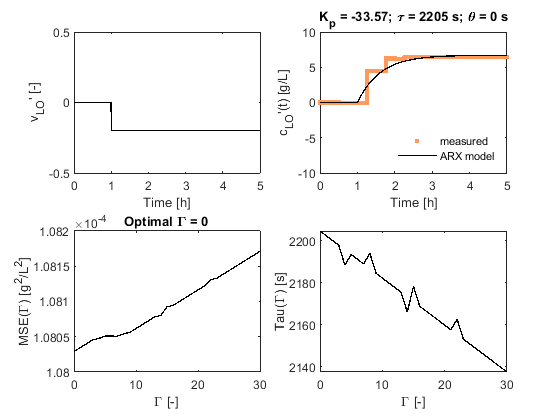

% Create the group of v_LO_control and c_LO
figure()

% PLot v_LO_control
subplot(2,2,1)
plot(STEP_V_LO_time_hours, STEP_V_LO_v_LO_control_prime, 'k-', 'LineWidth', 1)
ylabel("v_{LO}' [-]")
xlabel("Time [h]")
ylim([-0.5 0.5])
xlim([0 STEP_V_LO_time_hours(end)])

% Plot c_LO_measured
subplot(2,2,2)
plot(STEP_V_LO_time_hours, STEP_V_LO_c_LO_measured_prime, '.', 'MarkerSize', 8 ,'Color', orange)
hold on
plot(STEP_V_LO_c_LO_transfer_function_time_hours, STEP_V_LO_c_LO_transfer_function_results, 'k-','LineWidth', 1)
hold off
STEP_V_LO_c_LO_c_LO_title = sprintf('K_p = %.2f; \\tau = %.0f s; \\theta = %.0f s',STEP_V_LO_c_LO_Kp_optimal, STEP_V_LO_c_LO_tau_optimal, STEP_V_LO_c_LO_theta_optimal);
title(STEP_V_LO_c_LO_c_LO_title)
legend({'measured', 'ARX model'}, 'Location', 'southeast')
legend('boxoff')
ylabel("c_{LO}'(t) [g/L]")
xlabel("Time [h]")
ylim([-10 10])
xlim([0 STEP_V_LO_time_hours(end)])

% Plot the MSE
subplot(2,2,3)
plot([0:gamma_bound], STEP_V_LO_c_LO_MSE, 'k-','LineWidth', 1)
STEP_V_LO_c_LO_MSE_title = sprintf('Optimal \\Gamma = %.0f', STEP_V_LO_c_LO_gamma_optimal);
title(STEP_V_LO_c_LO_MSE_title)
ylabel("MSE(\Gamma) [g^{2}/L^{2}]")
xlabel("\Gamma [-]")
xlim([0 gamma_bound])

% Plot gamma
subplot(2,2,4)
plot([0:gamma_bound], STEP_V_LO_c_LO_tau, 'k-','LineWidth', 1)
ylabel("Tau(\Gamma) [s]")
xlabel("\Gamma [-]")
xlim([0 gamma_bound])

% Save the current figure
print('controller_tuning/output/step_v_LO_control_c_LO_prime_ARX_model', '-dpng', '-r600')

### Change in c_RE

### Plot the ARX model of c_RE

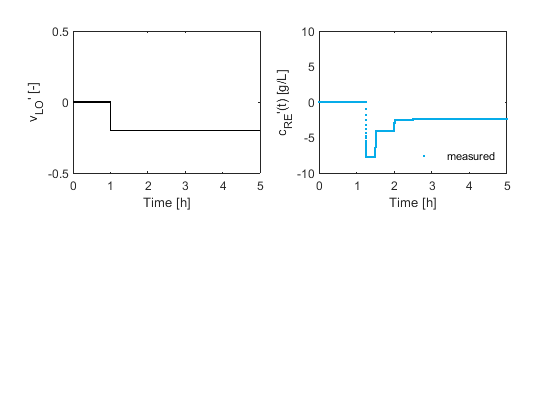

% Create the group of v_LO_control and c_RE
figure()

% PLot v_LO_control
subplot(2,2,1)
plot(STEP_V_LO_time_hours, STEP_V_LO_v_LO_control_prime, 'k-', 'LineWidth', 1)
ylabel("v_{LO}' [-]")
xlabel("Time [h]")
ylim([-0.5 0.5])
xlim([0 STEP_V_LO_time_hours(end)])

% Plot c_RE_measured
subplot(2,2,2)
plot(STEP_V_LO_time_hours, STEP_V_LO_c_RE_measured_prime, '.', 'MarkerSize', 4 ,'Color', blue)
legend({'measured'}, 'Location', 'southeast')
legend('boxoff')
ylabel("c_{RE}'(t) [g/L]")
xlabel("Time [h]")
ylim([-10 10])
xlim([0 STEP_V_LO_time_hours(end)])

% Save the current figure
print('controller_tuning/output/step_v_LO_control_c_RE_prime_ARX_model', '-dpng', '-r600')

## Step in v_LE

### Read the Step Data

STEP_V_LE_TABLE = readtable('controller_tuning/data/step_v_LE_control.csv');

### Extract the Data

% Extract the model time
STEP_V_LE_time          = STEP_V_LE_TABLE.Time;

% Extract the valve position of v_LO_control
STEP_V_LE_v_LE_control  = STEP_V_LE_TABLE.v_LE_control;

% Extract the controlled variables
STEP_V_LE_c_LO_measured = STEP_V_LE_TABLE.c_LO_measured;
STEP_V_LE_c_RE_measured = STEP_V_LE_TABLE.c_RE_measured;

### Deviation variable form

% Valve position
STEP_V_LE_v_LE_control_prime = STEP_V_LE_v_LE_control - STEP_V_LE_v_LE_control(1);

% Controlled variables
STEP_V_LE_c_LO_measured_prime = STEP_V_LE_c_LO_measured - STEP_V_LE_c_LO_measured(1);
STEP_V_LE_c_RE_measured_prime = STEP_V_LE_c_RE_measured - STEP_V_LE_c_RE_measured(1);

### Time step

STEP_V_LE_delta_t = STEP_V_LE_time(2) - STEP_V_LE_time(1);  % [s]

### Time in Hours

STEP_V_LE_time_hours = STEP_V_LE_time / (60*60);            % [h]

## Change in c_LO

### Plot the ARX model of c_LO

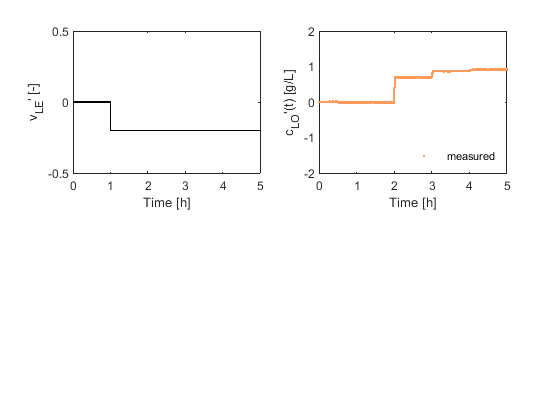

% Create the group of v_LE_control and c_LO
figure()

% PLot v_LE_control
subplot(2,2,1)
plot(STEP_V_LE_time_hours, STEP_V_LE_v_LE_control_prime, 'k-', 'LineWidth', 1)
ylabel("v_{LE}' [-]")
xlabel("Time [h]")
ylim([-0.5 0.5])
xlim([0 STEP_V_LE_time_hours(end)])

% Plot c_LO_measured
subplot(2,2,2)
plot(STEP_V_LE_time_hours, STEP_V_LE_c_LO_measured_prime, '.', 'MarkerSize', 4 ,'Color', orange)
legend({'measured'}, 'Location', 'southeast')
legend('boxoff')
ylabel("c_{LO}'(t) [g/L]")
xlabel("Time [h]")
ylim([-2 2])
xlim([0 STEP_V_LE_time_hours(end)])

% Save the current figure
print('controller_tuning/output/step_v_LE_control_c_LO_prime_ARX_model', '-dpng', '-r600')

### Change in c_RE

### Plot the ARX model of c_RE

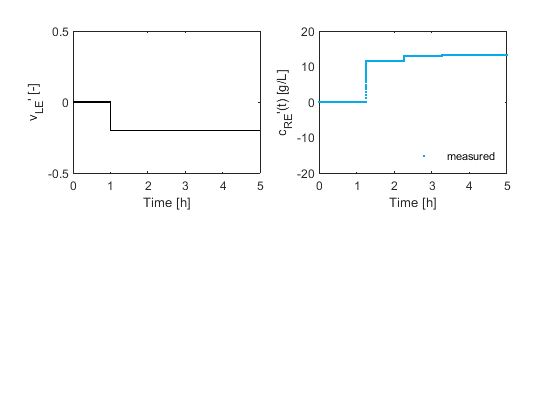

% Create the group of v_LE_control and c_RE
figure()

% PLot v_LE_control
subplot(2,2,1)
plot(STEP_V_LE_time_hours, STEP_V_LE_v_LE_control_prime, 'k-', 'LineWidth', 1)
ylabel("v_{LE}' [-]")
xlabel("Time [h]")
ylim([-0.5 0.5])
xlim([0 STEP_V_LE_time_hours(end)])

% Plot c_LO_measured
subplot(2,2,2)
plot(STEP_V_LE_time_hours, STEP_V_LE_c_RE_measured_prime, '.', 'MarkerSize', 4 ,'Color', blue)
legend({'measured'}, 'Location', 'southeast')
legend('boxoff')
ylabel("c_{RE}'(t) [g/L]")
xlabel("Time [h]")
ylim([-20 20])
xlim([0 STEP_V_LE_time_hours(end)])

% Save the current figure
print('controller_tuning/output/step_v_LE_control_c_RE_prime_ARX_model', '-dpng', '-r600')